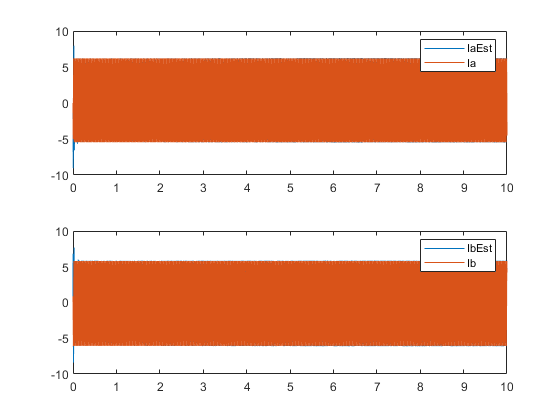

clc
clear all
%This section gives the simulation results of FSO&ParamEst with extra
%signal excitation, the parameters' EPE condition is satisfised.

%Simulation Steps
TsimMotor  = 1/(10e3*1e1);
TsimFSO    = 1/10e3;

%Rated Machine Parameter
RsRated = 0.8;
LdRated = 1.6e-3;
LqRated = 1.6e-3;
PsiPMRated= 0.054;

%Operation Condition
Id0 = -4;
Iq0 = 4;
F0  = 40;
we = F0*2*pi;
Ud0 = Id0*RsRated - we * LqRated * Iq0;
Uq0 = Iq0*RsRated + we * LdRated * Id0 + we * PsiPMRated;

%Extra Signal Excitation for parameters EPE condition
Udh = 1;
Uqh = 1;
Fh = 200;
psi_dh = 0;
psi_qh = pi/2;

%FSO Param
k = -0.8;
eta = -5.5;
KR = 20;
KL = 1e-4;

simulation = sim('IsoSM_ExtraSignalExcitation.slx');

Sim_IaEst = IaEst_Ia{1}.Values;
Sim_Ia    = IaEst_Ia{2}.Values;
Sim_IbEst = IbEst_Ib{1}.Values;
Sim_Ib    = IbEst_Ib{2}.Values;
figure()
subplot(2,1,1)
plot(Sim_IaEst.Time,Sim_IaEst.Data)
hold on
plot(Sim_IaEst.Time,Sim_Ia.Data)
hold off
% xlim([9 10])
ylim([-10 10])
legend('IaEst','Ia')
subplot(2,1,2)
plot(Sim_IbEst.Time,Sim_IbEst.Data)
hold on
plot(Sim_IbEst.Time,Sim_Ib.Data)
hold off
% xlim([9 10])
ylim([-10 10])
legend('IbEst','Ib')

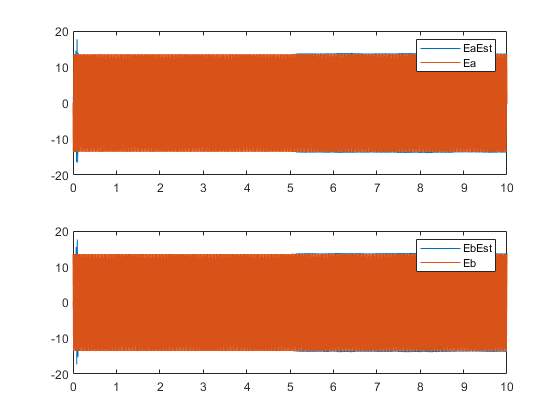



Sim_EaEst = EaEst_Ea{1}.Values;
Sim_Ea    = EaEst_Ea{2}.Values;
Sim_EbEst = EbEst_Eb{1}.Values;
Sim_Eb    = EbEst_Eb{2}.Values;
figure()
subplot(2,1,1)
plot(Sim_EaEst.Time,Sim_EaEst.Data)
hold on
plot(Sim_Ea.Time,Sim_Ea.Data)
hold off
% xlim([9 10])
% ylim([-10 10])
legend('EaEst','Ea')
subplot(2,1,2)
plot(Sim_EbEst.Time,Sim_EbEst.Data)
hold on
plot(Sim_Eb.Time,Sim_Eb.Data)
hold off
% xlim([9 10])
% ylim([-10 10])
legend('EbEst','Eb')

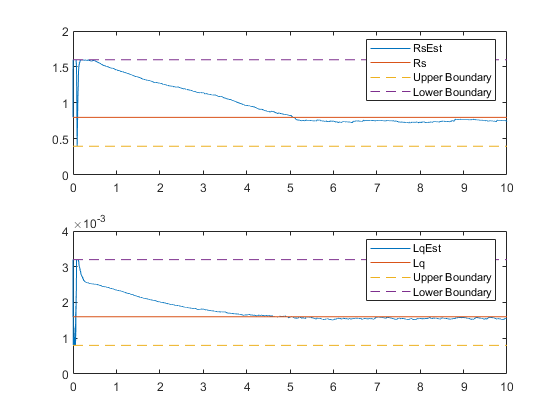


Sim_RsEst = RsEst{1}.Values;
Sim_LqEst = LqEst{1}.Values;

figure()
subplot(2,1,1)
plot(Sim_RsEst.Time,Sim_RsEst.Data)
hold on
plot([0 10],[RsRated RsRated])
plot([0 10],[RsRated*0.5 RsRated*0.5],'--')
plot([0 10],[RsRated*2.0 RsRated*2.0],'--')
hold off
ylim([0 RsRated*2.5])
legend('RsEst','Rs','Upper Boundary','Lower Boundary')

subplot(2,1,2)
plot(Sim_LqEst.Time,Sim_LqEst.Data)
hold on
plot([0 10],[LqRated LqRated])
plot([0 10],[LqRated*0.5 LqRated*0.5],'--')
plot([0 10],[LqRated*2.0 LqRated*2.0],'--')
hold off
ylim([0 LqRated*2.5])
legend('LqEst','Lq','Upper Boundary','Lower Boundary')

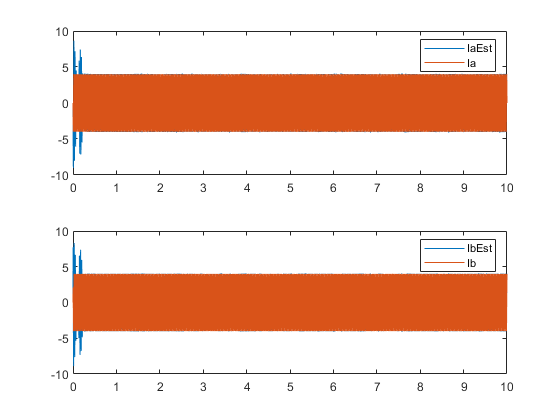

clc
clear all
%This section gives the simulation results of FSO&ParamEst without extra
%signal excitation, the parameters' EPE condition is not satisfised.

%Simulation Steps
TsimMotor  = 1/(10e3*1e1);
TsimFSO    = 1/10e3;

%Rated Machine Parameter
RsRated = 0.8;
LdRated = 1.6e-3;
LqRated = 1.6e-3;
PsiPMRated= 0.054;

%Operation Condition
Id0 = 0;
Iq0 = 4;
F0  = 40;
we = F0*2*pi;
Ud0 = Id0*RsRated - we * LqRated * Iq0;
Uq0 = Iq0*RsRated + we * LdRated * Id0 + we * PsiPMRated;

%The Amplitudes of Extra Signal Excitation are zero
Udh = 0;
Uqh = 0;
Fh = 200;
psi_dh = 0;
psi_qh = pi/2;

%FSO Param
k = -0.8;
eta = -5.5;
KR = 20;
KL = 1e-4;

simulation = sim('IsoSM_ExtraSignalExcitation.slx');

Sim_IaEst = IaEst_Ia{1}.Values;
Sim_Ia    = IaEst_Ia{2}.Values;
Sim_IbEst = IbEst_Ib{1}.Values;
Sim_Ib    = IbEst_Ib{2}.Values;
figure()
subplot(2,1,1)
plot(Sim_IaEst.Time,Sim_IaEst.Data)
hold on
plot(Sim_IaEst.Time,Sim_Ia.Data)
hold off
% xlim([9 10])
ylim([-10 10])
legend('IaEst','Ia')
subplot(2,1,2)
plot(Sim_IbEst.Time,Sim_IbEst.Data)
hold on
plot(Sim_IbEst.Time,Sim_Ib.Data)
hold off
% xlim([9 10])
ylim([-10 10])
legend('IbEst','Ib')

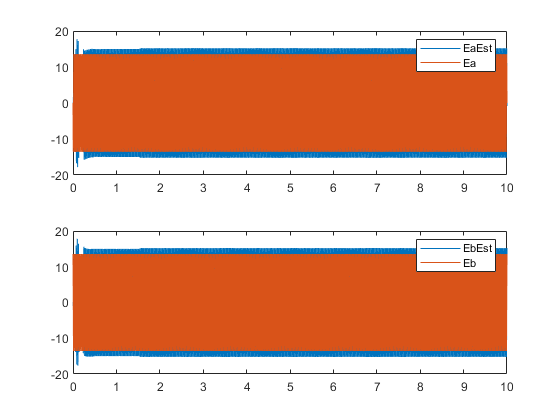



Sim_EaEst = EaEst_Ea{1}.Values;
Sim_Ea    = EaEst_Ea{2}.Values;
Sim_EbEst = EbEst_Eb{1}.Values;
Sim_Eb    = EbEst_Eb{2}.Values;
figure()
subplot(2,1,1)
plot(Sim_EaEst.Time,Sim_EaEst.Data)
hold on
plot(Sim_Ea.Time,Sim_Ea.Data)
hold off
% xlim([9 10])
% ylim([-10 10])
legend('EaEst','Ea')
subplot(2,1,2)
plot(Sim_EbEst.Time,Sim_EbEst.Data)
hold on
plot(Sim_Eb.Time,Sim_Eb.Data)
hold off
% xlim([9 10])
% ylim([-10 10])
legend('EbEst','Eb')

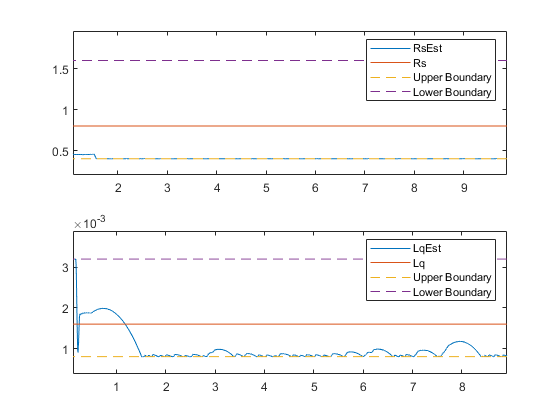


Sim_RsEst = RsEst{1}.Values;
Sim_LqEst = LqEst{1}.Values;

figure()
subplot(2,1,1)
plot(Sim_RsEst.Time,Sim_RsEst.Data)
hold on
plot([0 10],[RsRated RsRated])
plot([0 10],[RsRated*0.5 RsRated*0.5],'--')
plot([0 10],[RsRated*2.0 RsRated*2.0],'--')
hold off
ylim([0 RsRated*2.5])
legend('RsEst','Rs','Upper Boundary','Lower Boundary')

subplot(2,1,2)
plot(Sim_LqEst.Time,Sim_LqEst.Data)
hold on
plot([0 10],[LqRated LqRated])
plot([0 10],[LqRated*0.5 LqRated*0.5],'--')
plot([0 10],[LqRated*2.0 LqRated*2.0],'--')
hold off
ylim([0 LqRated*2.5])
legend('LqEst','Lq','Upper Boundary','Lower Boundary')

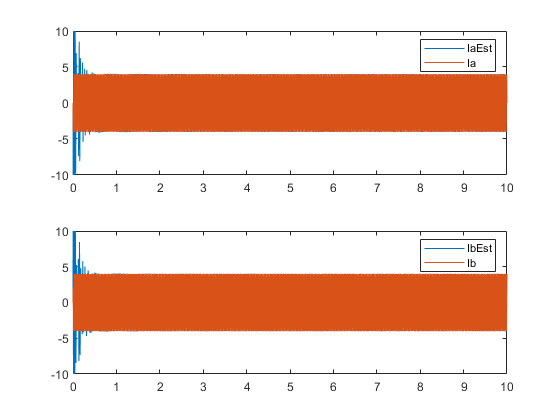

clc
clear all
%This section gives the simulation results of FSO&ParamEst without extra
%signal excitation, the parameters' EPE condition is not satisfised.

%Simulation Steps
TsimMotor  = 1/(10e3*1e1);
TsimFSO    = 1/10e3;

%Rated Machine Parameter
RsRated = 0.8;
LdRated = 1.6e-3;
LqRated = 1.6e-3;
PsiPMRated= 0.054;

%Operation Condition
Id0 = 0;
Iq0 = 4;
F0  = 40;
we = F0*2*pi;
Ud0 = Id0*RsRated - we * LqRated * Iq0;
Uq0 = Iq0*RsRated + we * LdRated * Id0 + we * PsiPMRated;


%FSO Param
k = -0.8;
eta = -5.5;

OnlyRsEstimation = false; % False for only Lq Estimation

FixedEamAssumption = false; 
% the simulation and analysis shows that in single parameter estimation,
% A perfect known Eam of Psiam is needed
if OnlyRsEstimation
    KR = RsRated * 0.5;
    KL = 0;
else
    KR = 0;
    KL = LqRated * 0.5;
end

simulation = sim('IsoSM_SingleParamEst.slx');

Sim_IaEst = IaEst_Ia{1}.Values;
Sim_Ia    = IaEst_Ia{2}.Values;
Sim_IbEst = IbEst_Ib{1}.Values;
Sim_Ib    = IbEst_Ib{2}.Values;
figure()
subplot(2,1,1)
plot(Sim_IaEst.Time,Sim_IaEst.Data)
hold on
plot(Sim_IaEst.Time,Sim_Ia.Data)
hold off
% xlim([9 10])
ylim([-10 10])
legend('IaEst','Ia')
subplot(2,1,2)
plot(Sim_IbEst.Time,Sim_IbEst.Data)
hold on
plot(Sim_IbEst.Time,Sim_Ib.Data)
hold off
% xlim([9 10])
ylim([-10 10])
legend('IbEst','Ib')

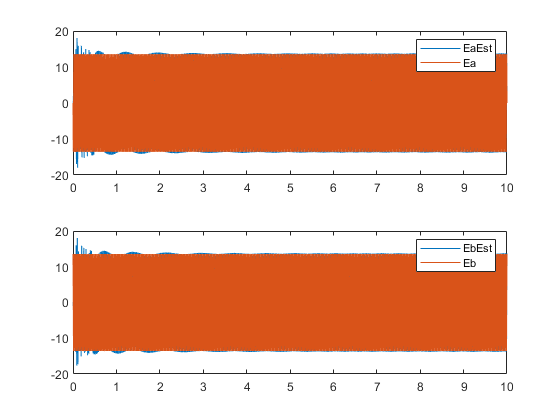



Sim_EaEst = EaEst_Ea{1}.Values;
Sim_Ea    = EaEst_Ea{2}.Values;
Sim_EbEst = EbEst_Eb{1}.Values;
Sim_Eb    = EbEst_Eb{2}.Values;
figure()
subplot(2,1,1)
plot(Sim_EaEst.Time,Sim_EaEst.Data)
hold on
plot(Sim_Ea.Time,Sim_Ea.Data)
hold off
% xlim([9 10])
% ylim([-10 10])
legend('EaEst','Ea')
subplot(2,1,2)
plot(Sim_EbEst.Time,Sim_EbEst.Data)
hold on
plot(Sim_Eb.Time,Sim_Eb.Data)
hold off
% xlim([9 10])
% ylim([-10 10])
legend('EbEst','Eb')

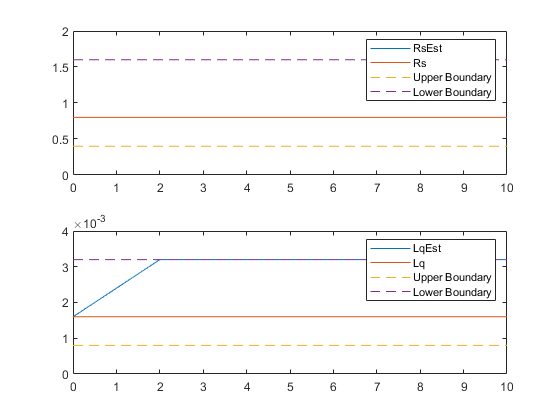


Sim_RsEst = RsEst{1}.Values;
Sim_LqEst = LqEst{1}.Values;

figure()
subplot(2,1,1)
plot(Sim_RsEst.Time,Sim_RsEst.Data)
hold on
plot([0 10],[RsRated RsRated])
plot([0 10],[RsRated*0.5 RsRated*0.5],'--')
plot([0 10],[RsRated*2.0 RsRated*2.0],'--')
hold off
ylim([0 RsRated*2.5])
legend('RsEst','Rs','Upper Boundary','Lower Boundary')

subplot(2,1,2)
plot(Sim_LqEst.Time,Sim_LqEst.Data)
hold on
plot([0 10],[LqRated LqRated])
plot([0 10],[LqRated*0.5 LqRated*0.5],'--')
plot([0 10],[LqRated*2.0 LqRated*2.0],'--')
hold off
ylim([0 LqRated*2.5])
legend('LqEst','Lq','Upper Boundary','Lower Boundary')